addpath csi_tool_box\


% 显示三个天线的所有子载波
clc
clear;
close all;

csi_trace = read_bf_file('..\data\7-21-1.dat');

size(csi_trace)

ans =        73815           1



csi_entry = csi_trace{10000}

csi_entry = 包含以下字段的 struct :
    timestamp_low: 136526986
       bfee_count: 10000
              Nrx: 3
              Ntx: 1
           rssi_a: 38
           rssi_b: 37
           rssi_c: 21
            noise: -127
              agc: 51
             perm: [1 2 3]
             rate: 257
              csi: [1×3×30 double]


ans =           30       32616           3


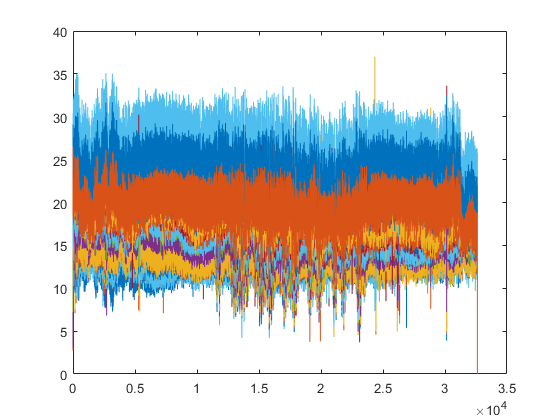

ans =           30       32616           3


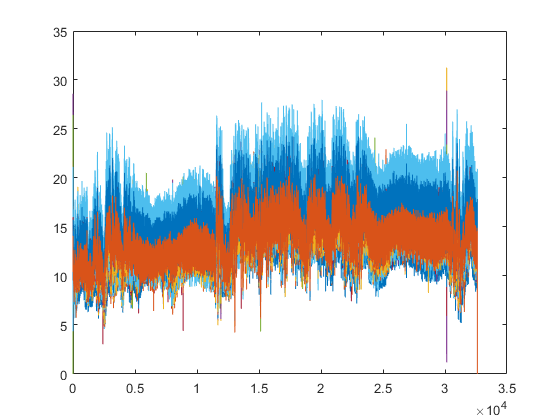

ans =           30       32616           3


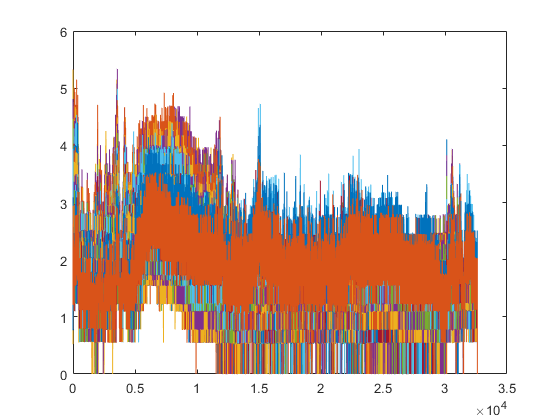


% 可能有空包
for i = 1:length(csi_trace)
    csi_entry = csi_trace{i};
    
    if isempty(csi_entry)
        break
    end
end

ant_csi = zeros(30,i,3);

for j = 1:3
  for i = 1:size(ant_csi,2)-1       % 这里是取的数据包的个数
      
    csi_entry = csi_trace{i};   % 类似于字典
    
    csi = get_scaled_csi(csi_entry);    % 提取csi矩阵   [1,3,30]    
    csi = csi(1,:,:);                   % csi_shape =  [3,30]
    csi1= abs(squeeze(csi).');          % csi1_shape = [30,3]

    ant_csi(:,i,j)=csi1(:,j);           %仅获得一个天线上的CSI数据
    
  end
  figure(j);
  size(ant_csi)
  plot(ant_csi(:,:,j).');
  hold on
end

size(ant_csi)

ans =           30       32616           3


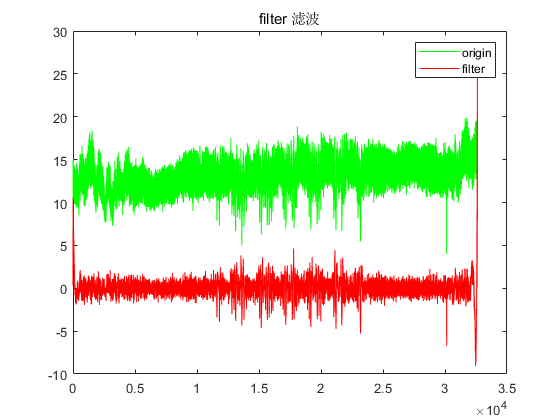

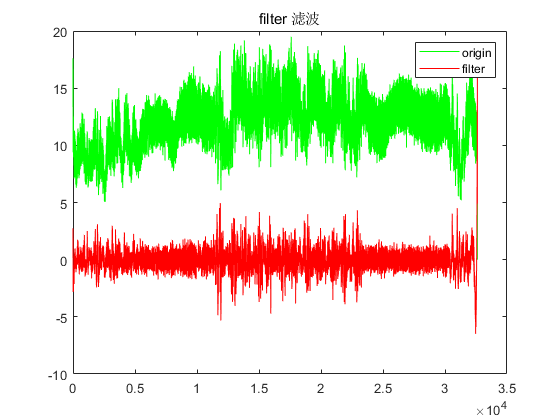

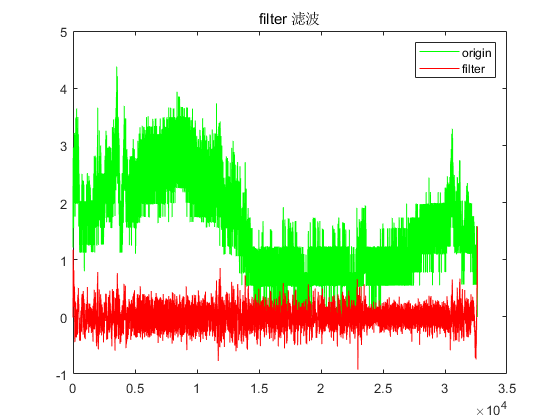

samp_rate = 1000;
half_rate = samp_rate / 2;
uppe_orde = 6;
uppe_stop = 120;
lowe_orde = 3;
lowe_stop = 2;

[lu,ld] = butter(uppe_orde,uppe_stop/half_rate,'low');  % 低通滤波
[hu,hd] = butter(lowe_orde,lowe_stop/half_rate,'high'); % 高通滤波

csi_r1_ff = abs(ant_csi);

for j = 1:3
    for i = 1:30
    csi_r1_ff(i,:,j) = filtfilt(lu,ld,csi_r1_ff(i,:,j));
    csi_r1_ff(i,:,j) = filtfilt(hu,hd,csi_r1_ff(i,:,j));
    end
end


for j = 1:3
    figure
    plot(abs(ant_csi(1,:,j)),'g'); hold on
    plot(csi_r1_ff(1,:,j),'r')
    title('filter 滤波'); legend('origin', 'filter')
end

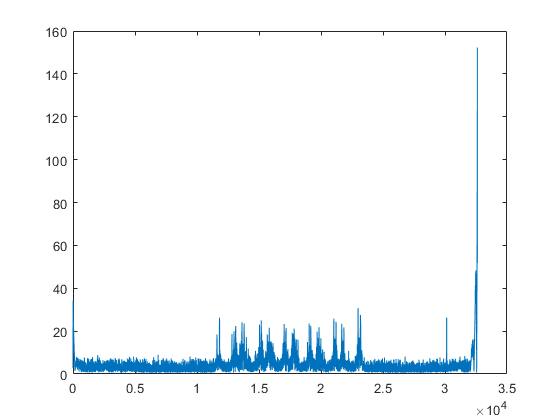

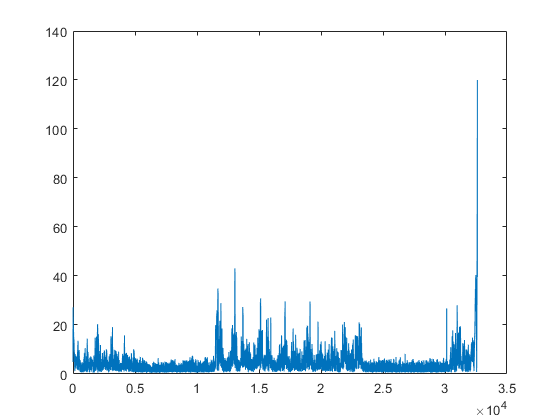

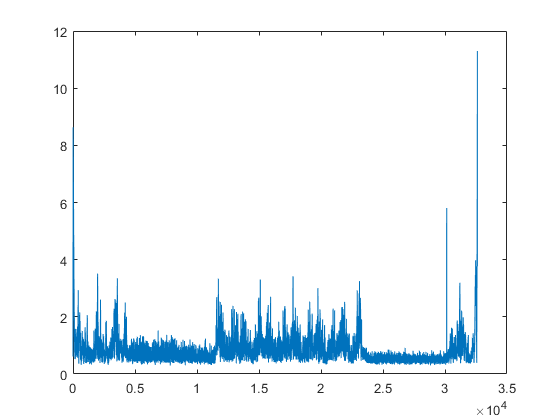


csi_r1_pca = zeros(size(csi_r1_ff,2), 3);

for j = 1:3
    pca_coef = pca(squeeze(abs(csi_r1_ff(1:30,:,j))).');
    csi_r1_pca(:,j) = squeeze(abs(csi_r1_ff(1:30,:,j))).' * pca_coef(:,1);
    figure
    plot(csi_r1_pca(:,j))
end

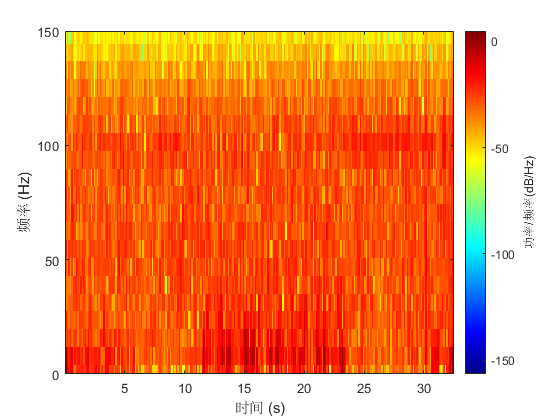

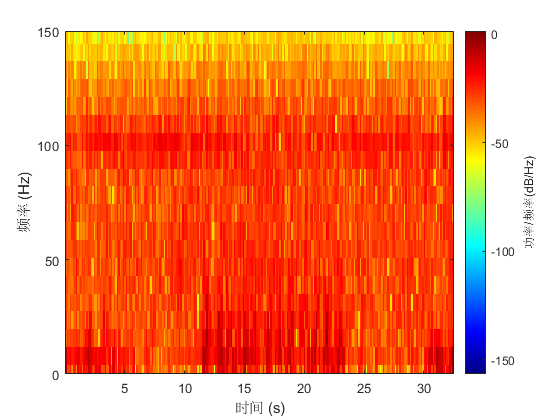

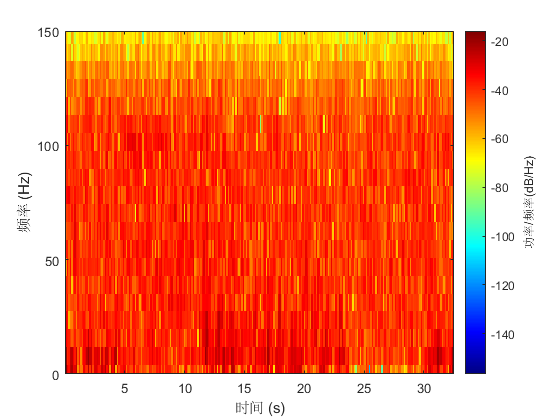


for j = 1:3
    figure
    spectrogram(csi_r1_ff(1,:,j),128,1,128,1000,'yaxis')
    colormap(jet);
    ylim([0 150])
end

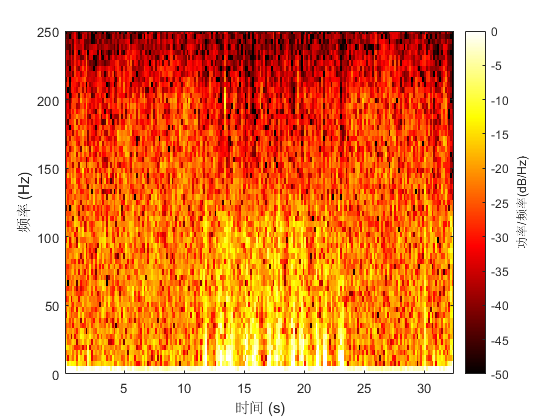

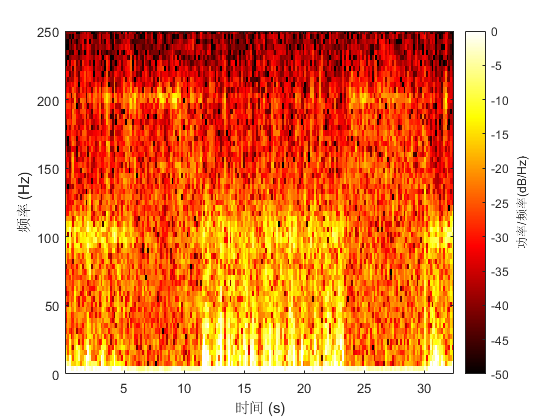

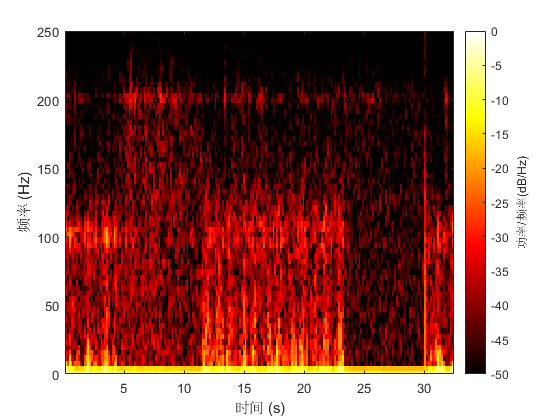


for j = 1:3
    figure
    spectrogram(csi_r1_pca(:,j),256,100,256,1000,'yaxis')
    colormap("hot");
    caxis([-50,0])
    ylim([0 250])
end